2. Consider the problem from lab sheet 03, ie minimise


$$F\left(x,y\right)=\lambda \left(\sin \left(x\right)+\sin \left(y\right)\right)-x-2y$$


subject to x, y ≥ 0, and x, y ≤ R (eg R = 40), where eg λ = 3.

(a) Explore how to use use multistart and fmincon to solve this problem.

clc; clear all; close all;
lam = 3;
R = 40;

fun = @(x)lam * (sin(x(1) + sin(x(2)))) - x(1) - 2*x(1);
funy = @(x, y)lam * (sin(x) + sin(y)) - x - 2*y;

fcontour(funy, [0 R 0 R],'Fill','on')
x0 = [35, 35];
lb = [0, 0];
ub = [R, R];


opts = optimoptions(@fmincon,'Algorithm','sqp');
problem = createOptimProblem('fmincon','objective',...
    fun,'x0',x0,'lb',lb,'ub',ub,'options',opts);

ms = MultiStart;

[x,f] = run(ms,problem,20)

MultiStart completed the runs from all start points.

All 20 local solver runs converged with a positive local solver exit flag.


x =    40.0000    7.8540


f = -120.4759

hold on
plot(x(1), x(2), '.', 'MarkerSize',20)

(b) Write your own multistart solver, that generates random initial solution guesses, calls fmincon,

and pools the local minima found.

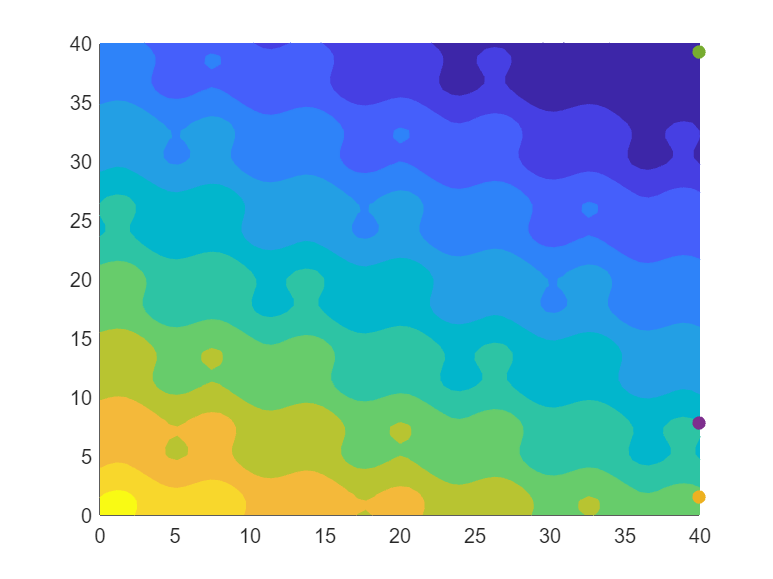

minValue = -120.4759

minValue = -120.4759

minValue = -120.4759

minValue = -120.4759

xn = 20;
x0_x = 0 : R/xn : R;
x0_y = 0 : R/xn : R;

x0_all = [x0_x' x0_y'];

minValue = inf;
options = optimoptions('fmincon', 'Display','off');

for i = 1: xn
    x0 = x0_all(i, :);
    [x,fval] = fmincon(fun,x0,[],[],[],[],lb,ub,[], options);
    
    if fval < minValue
        minValue = fval
        plot(x(1), x(2), '.', 'MarkerSize',20)
        solution = x;
    end
end

(c) Attempt to apply other solvers to this problem.

[`ga`](https://uk.mathworks.com/help/gads/ga.html)`, `[`gamultiobj`](https://uk.mathworks.com/help/gads/gamultiobj.html)`, `[`paretosearch`](https://uk.mathworks.com/help/gads/paretosearch.html)`, `[`particleswarm`](https://uk.mathworks.com/help/gads/particleswarm.html)`, `[`patternsearch`](https://uk.mathworks.com/help/gads/patternsearch.html)`, `[`simulannealbnd`](https://uk.mathworks.com/help/gads/simulannealbnd.html)`, `[`surrogateopt`](https://uk.mathworks.com/help/gads/surrogateopt.html)

%%
tic
[x,fval] = ga(fun,2,[],[],[],[],lb,ub)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =    40.0000    7.8540


fval = -120.4759

toc

Elapsed time is 0.632816 seconds.


tic
[x,fval] = gamultiobj(fun,2,[],[],[],[],lb,ub)

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


x =    40.0000   32.9867


fval = -120.4759

toc

Elapsed time is 0.425230 seconds.


tic
[x,fval] = paretosearch(fun,2,[],[],[],[],lb,ub)


Pareto set found that satisfies the constraints. 

Mesh size of all incumbents less than 'options.MeshTolerance' and constraints are 
satisfied to with 'options.ConstraintTolerance'.



x =    40.0000    1.5708


fval = -120.4759

toc

Elapsed time is 2.680627 seconds.


tic
[x,fval] = particleswarm(fun,2,lb,ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =    40.0000    7.8535


fval = -120.4759

toc

Elapsed time is 0.238172 seconds.


tic
[x,fval] = patternsearch(fun,[0,0],[],[],[],[],lb,ub)

Optimization terminated: mesh size less than options.MeshTolerance.


x =    40.0000   39.2699


fval = -120.4759

toc

Elapsed time is 0.230463 seconds.
